clc
clear
close all


%% Create the convolution filter

r = 0.9;                             % Define filter
om = 0.95;
a = [1 -2*r*cos(om) r^2];
b = [1 r*cos(om)];
h = filter(b, a, [zeros(1,38) 1 zeros(1,40)]);
N = 500;
K = 25;
sigma = 1;


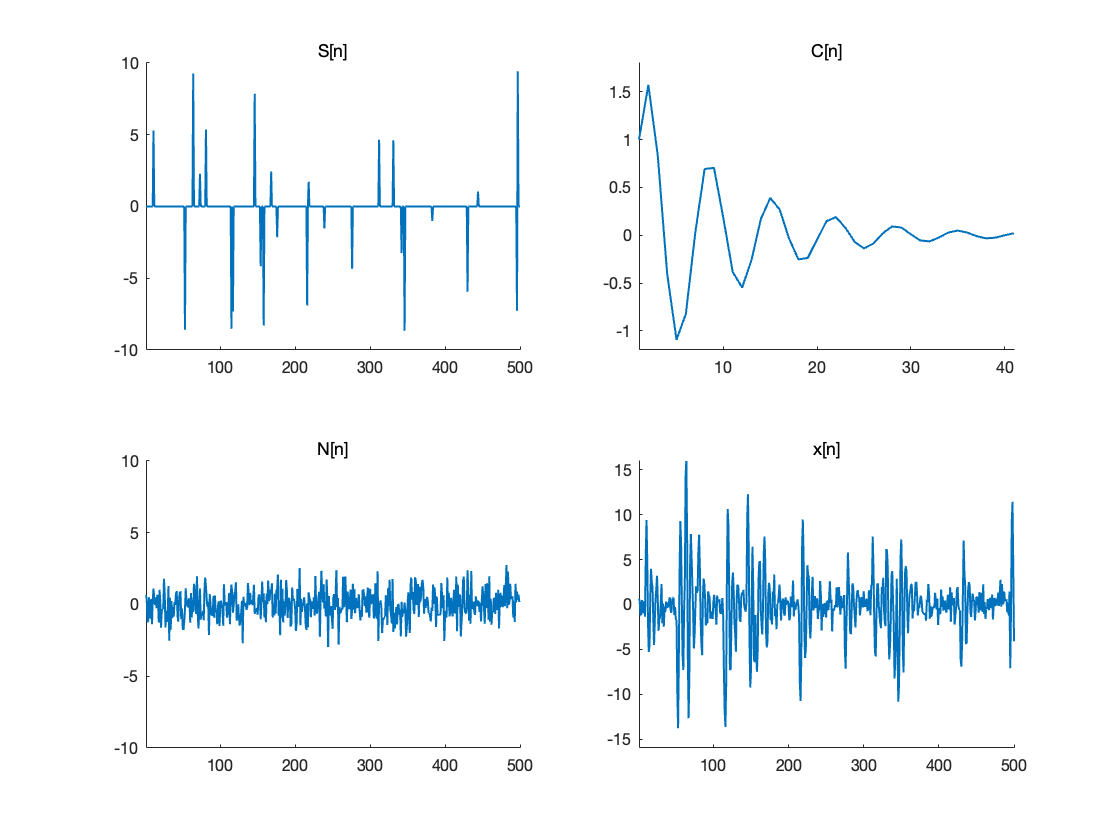

%% Plot the components of the input signal

set_plot_defaults('on')
hh = filter(b, a, [1 zeros(1,40)]);

groundtruth = zeros(1, N);
index_random = randperm(N);
index = index_random(1:K);
groundtruth(index) = 10*2*(rand(1,K) - 0.5);
after_conv = conv(groundtruth,h,'same');
noise = sigma * randn(1,N);
input = after_conv + noise;

figure(1)

subplot(2,2,1)
plot(1:N, groundtruth)
title('S[n]')
ylim([-10 10])
xlim([1,500])

box off

subplot(2,2,2)
plot(1:41, hh)
title('C[n]')
ylim([-1.2 1.8])
xlim([1,41])

box off

subplot(2,2,3)
plot(1:N, noise)
title('N[n]')
ylim([-10 10])
xlim([1,500])

box off

subplot(2,2,4)
plot(1:N, input)
title('x[n]')
ylim([-16 16])
xlim([1,500])

box off


% set(gcf, 'PaperPosition', [1 1 14 6])

% print -depsc figures/input

set_plot_defaults('off')


%% Load the 3-layer deconvolution CNN

load('sin2.mat');
deconvolver{1} = double(conv1);
deconvolver{2} = double(conv2);
deconvolver{3} = double(conv3);
% deconvolver{4} = double(conv4);
% deconvolver{5} = double(conv5);


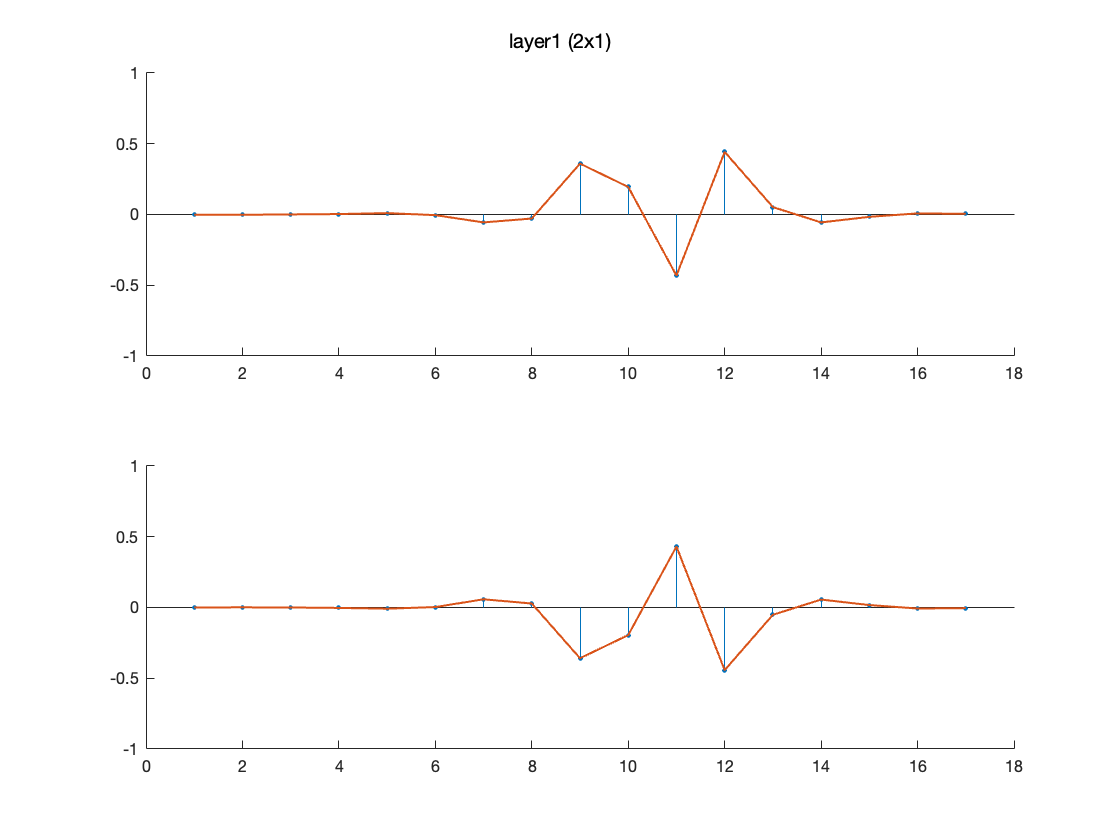

%% Plot the structure of the 3-layer CNN

set_plot_defaults('on')
figure(2)
[r,c,~] = size(deconvolver{1});
for i=1:1:r
    for j=1:1:c
        subplot(r,c,c*i-(c-j))
        stem(flip(squeeze(deconvolver{1}(i,j,:))), 'filled', 'MarkerSize', 2)
        hold on
        plot(flip(squeeze(deconvolver{1}(i,j,:))))
        hold off
        xlim([0,18])
        ylim([-1,1])
        box off
    end
end
sgtitle('layer1 (2x1)', 'FontSize', 10);

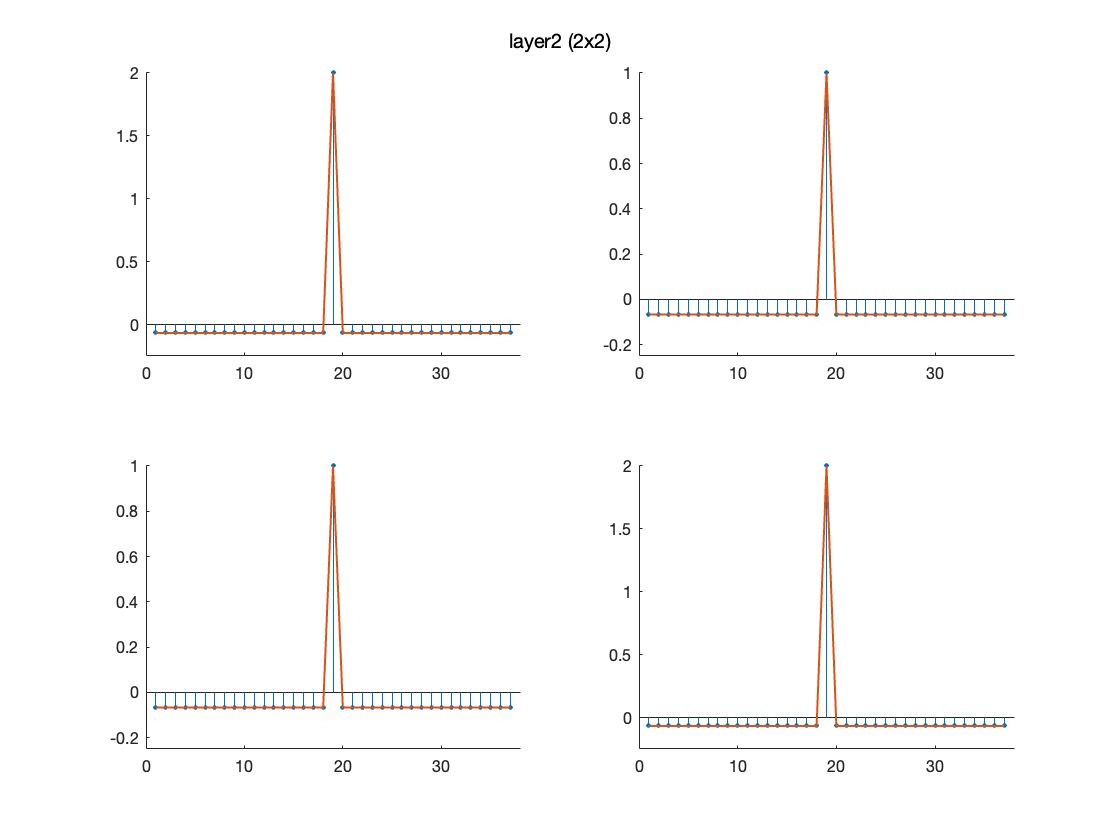


% set(gcf, 'PaperPosition', [1 1 3 6])

% print -depsc figures/layer1

figure(3)
title('Layer 2')
[r,c,~] = size(deconvolver{2});
for i=1:1:r
    for j=1:1:c
        subplot(r,c,c*i-(c-j))
        stem(flip(squeeze(deconvolver{2}(i,j,:))), 'filled', 'MarkerSize', 2)
        hold on
        plot(flip(squeeze(deconvolver{2}(i,j,:))))
        hold off
        xlim([0,38])
        ylim([-0.25,inf])
        box off
    end
end
sgtitle('layer2 (2x2)', 'FontSize', 10);

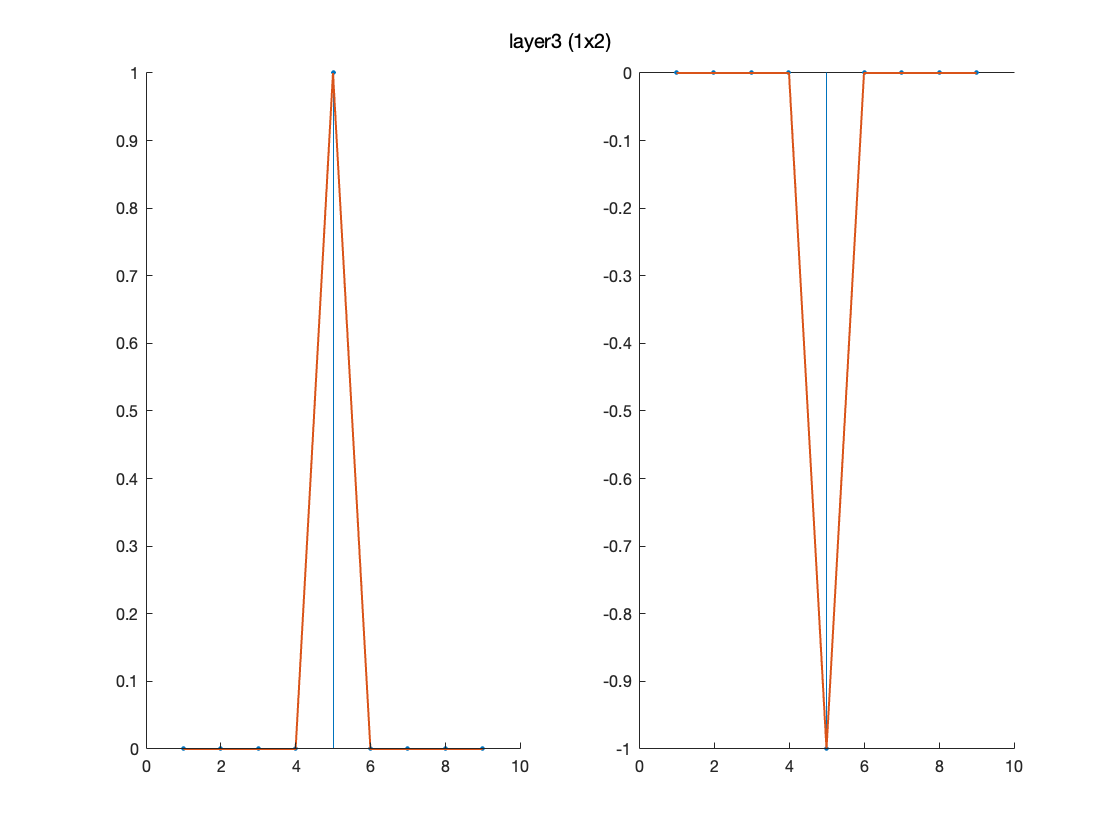


% set(gcf, 'PaperPosition', [1 1 6 6])

% print -depsc figures/layer2

figure(4)
title('Layer 3')
[r,c,~] = size(deconvolver{3});
for i=1:1:r
    for j=1:1:c
        subplot(r,c,c*i-(c-j))
        stem(flip(squeeze(deconvolver{3}(i,j,:))), 'filled', 'MarkerSize', 2)
        hold on
        plot(flip(squeeze(deconvolver{3}(i,j,:))))
        hold off
        box off
    end
end
sgtitle('layer3 (1x2)', 'FontSize', 10);


% set(gcf, 'PaperPosition', [1 1 6 6])

% print -depsc figures/layer3

set_plot_defaults('off')



%% Load the proposed CNN

load('sin23_2.mat');
deconvolver{1} = double(conv1);
deconvolver{2} = double(conv2);
deconvolver{3} = double(conv3);
deconvolver{4} = double(conv4);
deconvolver{5} = double(conv5);



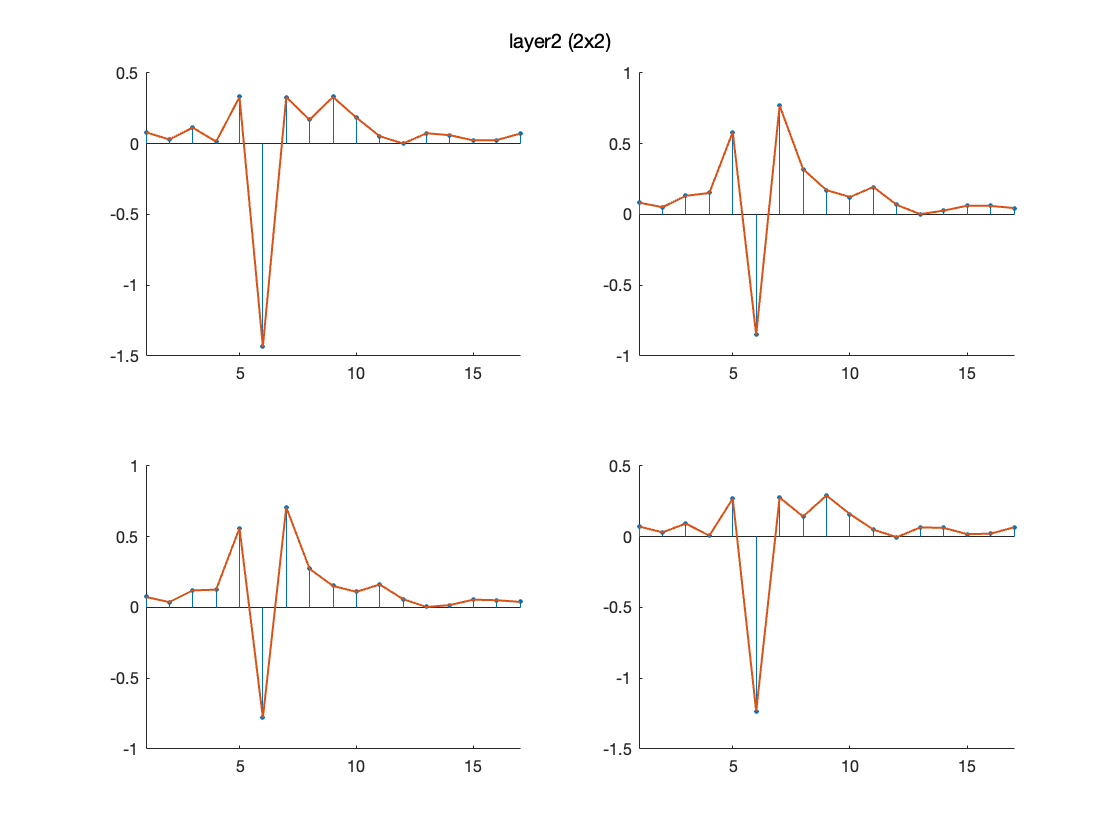

%% Plot the second and third layer of the proposed CNN

set_plot_defaults('on')
figure(5)
[r,c,~] = size(deconvolver{2});
for i=1:1:r
    for j=1:1:c
        subplot(r,c,c*i-(c-j))
        stem(flip(squeeze(deconvolver{2}(i,j,:))), 'filled', 'MarkerSize', 2)
        hold on
        plot(flip(squeeze(deconvolver{2}(i,j,:))))
        hold off
        xlim([1,17])
        box off
    end
end
sgtitle('layer2 (2x2)', 'FontSize', 10);

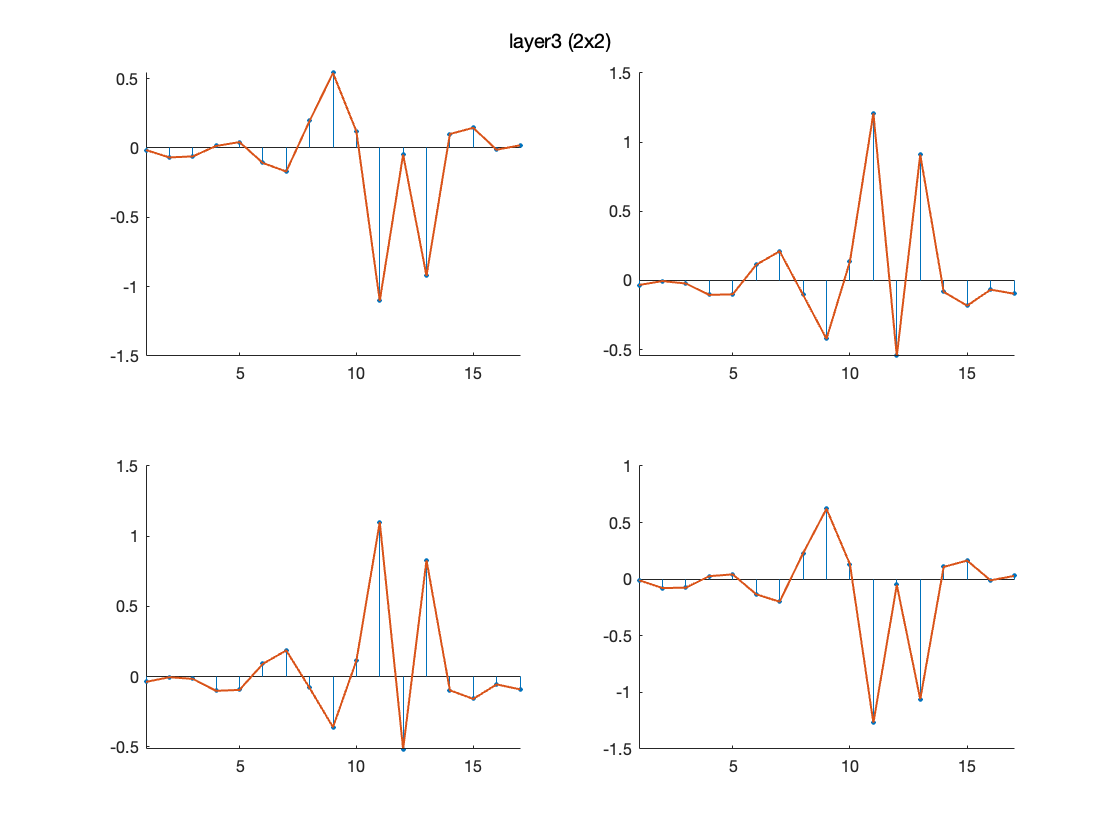


% set(gcf, 'PaperPosition', [1 1 6 6])

% print -depsc figures/layer2_retrain

figure(6)
[r,c,~] = size(deconvolver{3});
for i=1:1:r
    for j=1:1:c
        subplot(r,c,c*i-(c-j))
        stem(flip(squeeze(deconvolver{3}(i,j,:))), 'filled', 'MarkerSize', 2)
        hold on
        plot(flip(squeeze(deconvolver{3}(i,j,:))))
        hold off
        xlim([1,17])
        box off
    end
end
sgtitle('layer3 (2x2)', 'FontSize', 10);


% set(gcf, 'PaperPosition', [1 1 6 6])

% print -depsc figures/layer3_retrain

set_plot_defaults('off')


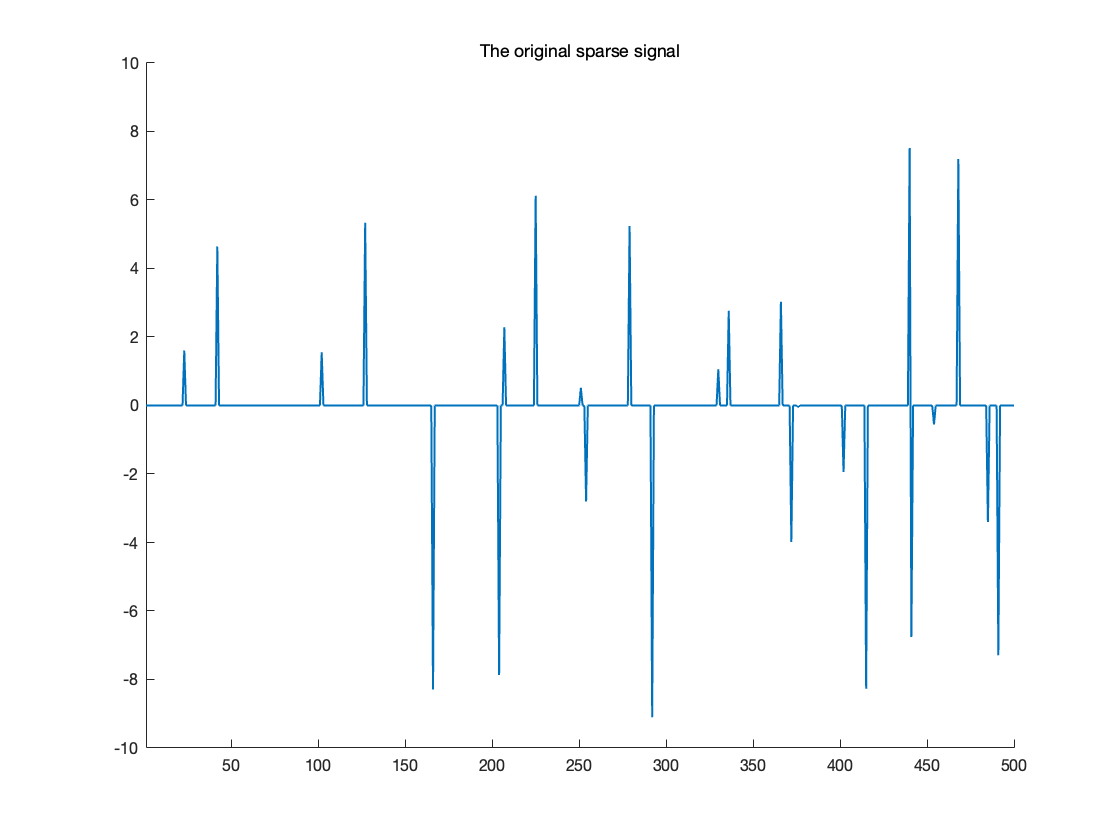

%% Plot the output of each layer

set_plot_defaults('on')

groundtruth = zeros(1, N);
index_random = randperm(N);
index = index_random(1:K);
groundtruth(index) = 10*2*(rand(1,K) - 0.5);
after_conv = conv(groundtruth,h,'same');
noise = sigma * randn(1,N);
input = after_conv + noise;

figure(7)
plot(1:N, groundtruth)
title('The original sparse signal')
xlim([1,500])
ylim([-10,10])
box off

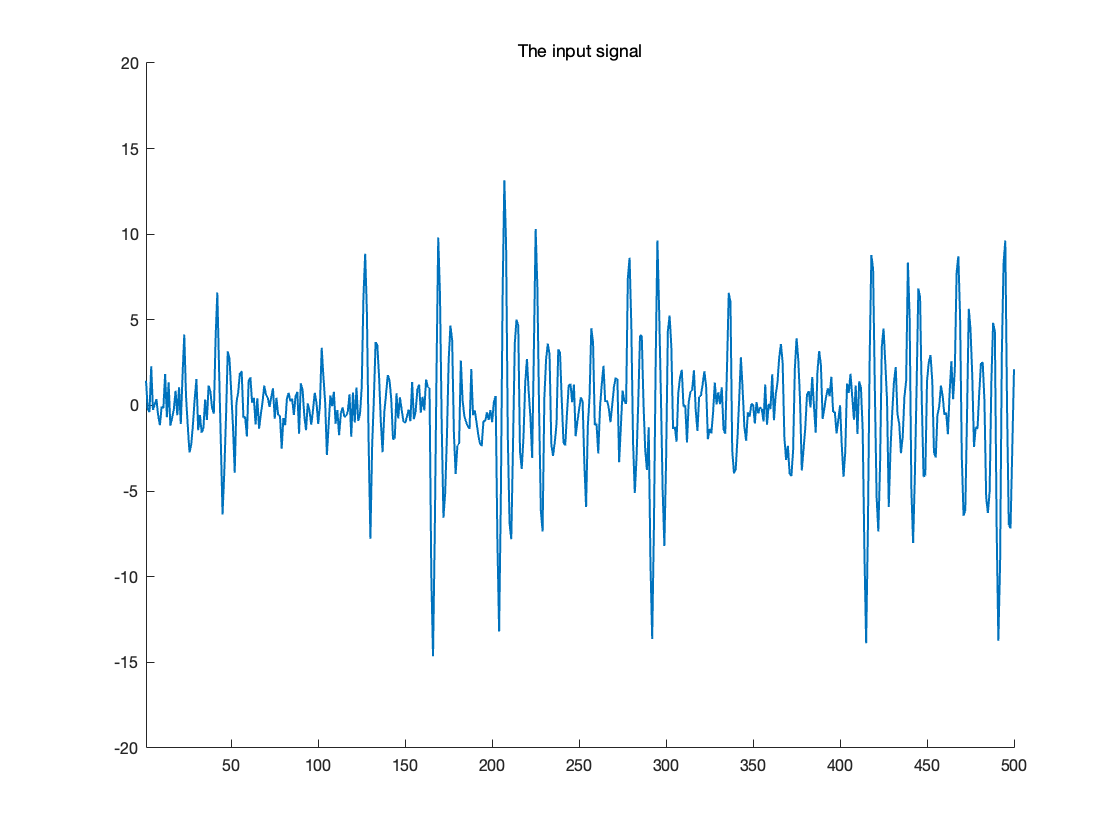


% set(gcf, 'PaperPosition', [1 1 6 6])

% print -depsc figures/original

figure(8)
plot(1:N, input)
title('The input signal')
xlim([1,500])
ylim([-20,20])
box off


% set(gcf, 'PaperPosition', [1 1 6 6])

% print -depsc figures/input_retrain


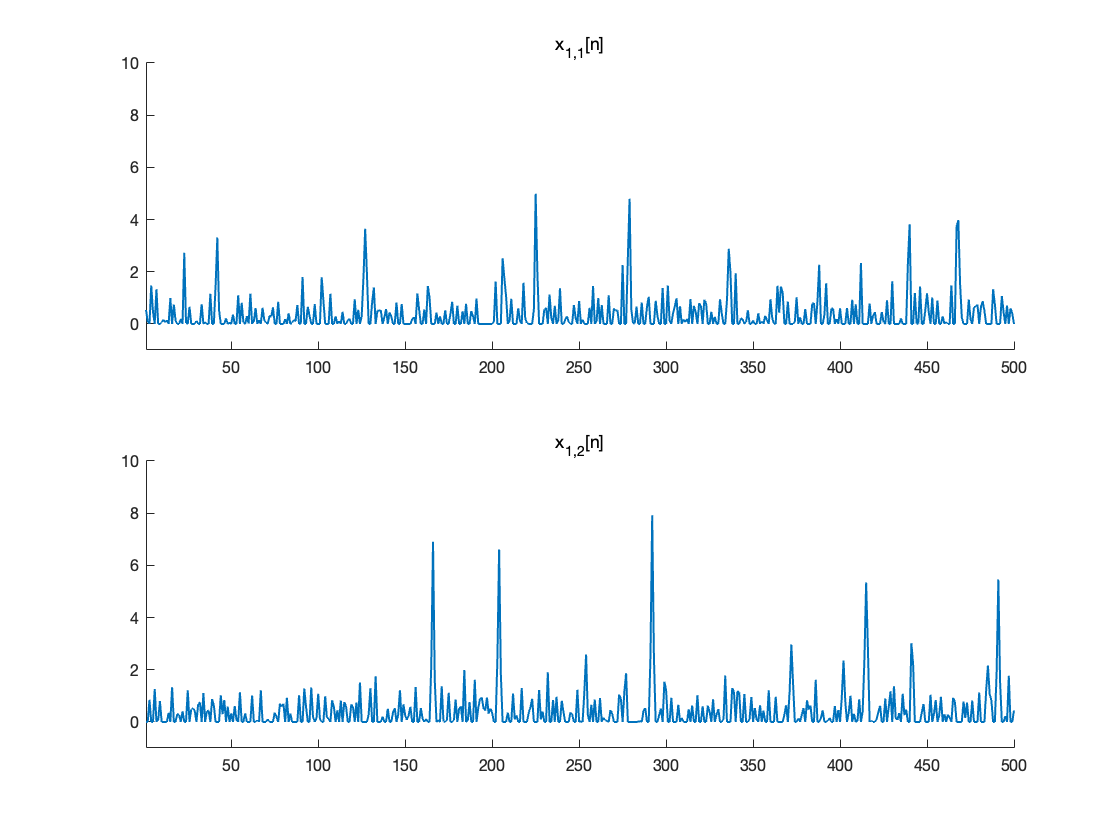

%% Plot the output of each layer

set_plot_defaults('on')

l1 = layer(input,deconvolver{1});
l2 = layer(l1,deconvolver{2});
l3 = layer(l2,deconvolver{3});
l4 = layer(l3,deconvolver{4});
output = CNN(input,deconvolver);

figure(9)
subplot(2,1,1)
plot(1:N, l1(1,:))
title('x_{1,1}[n]')
xlim([1,500])
ylim([-1,10])
box off
subplot(2,1,2)
plot(1:N, l1(2,:))
title('x_{1,2}[n]')
xlim([1,500])
ylim([-1,10])
box off

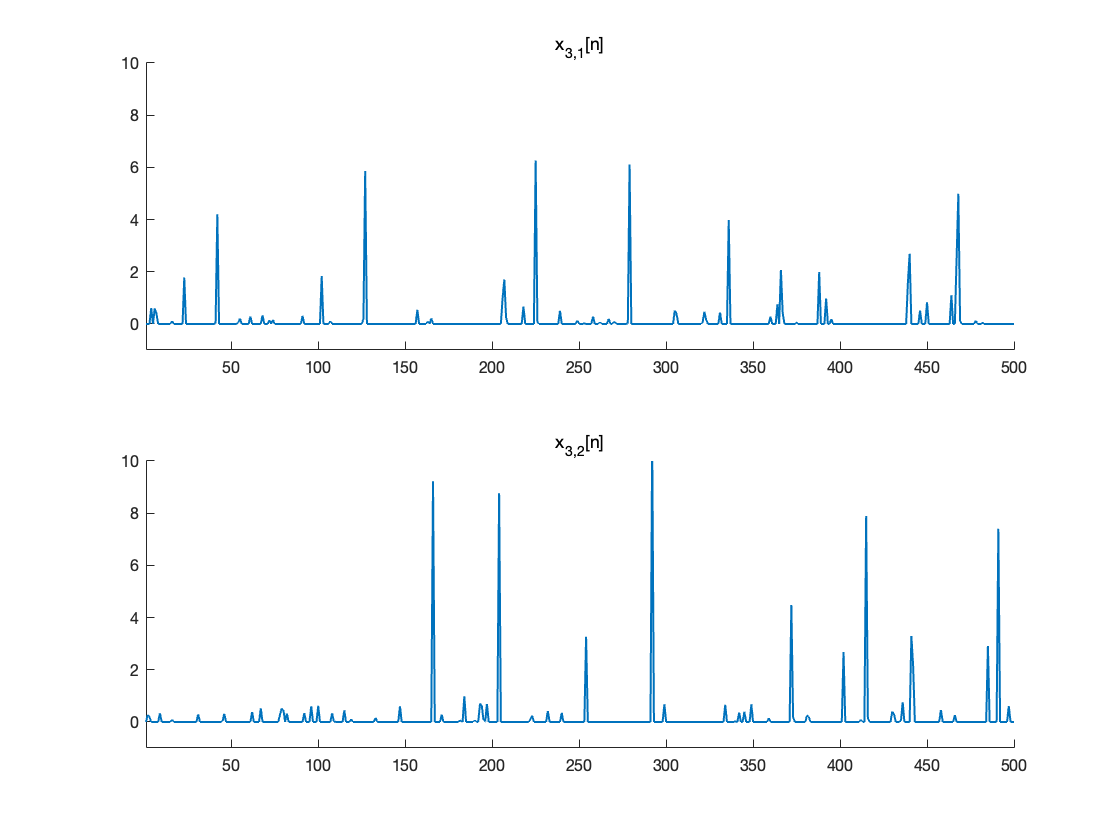

% set(gcf, 'PaperPosition', [1 1 6 6])

% print -depsc figures/output1_retrain

figure(10)
subplot(2,1,1)
plot(1:N, l3(1,:))
title('x_{3,1}[n]')
xlim([1,500])
ylim([-1,10])
box off
subplot(2,1,2)
plot(1:N, l3(2,:))
title('x_{3,2}[n]')
xlim([1,500])
ylim([-1,10])
box off

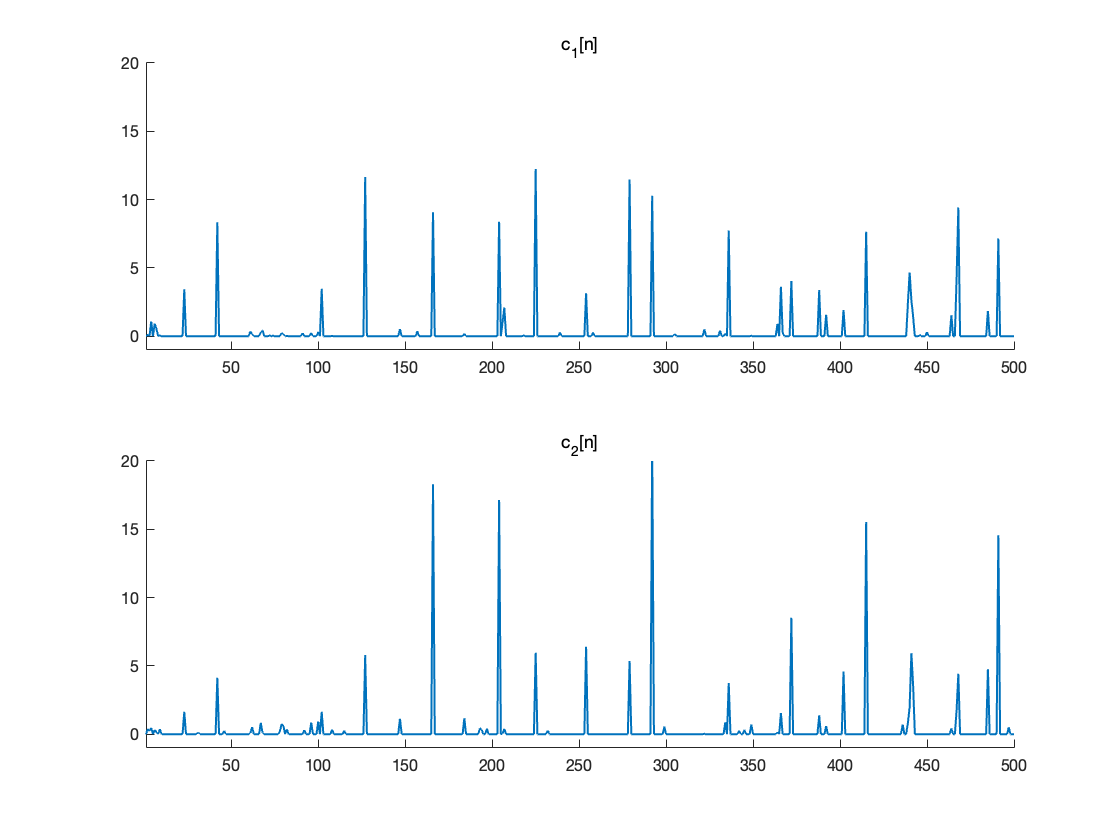

% set(gcf, 'PaperPosition', [1 1 6 6])

% print -depsc figures/output3_retrain

figure(11)
subplot(2,1,1)
plot(1:N, l4(1,:))
title('c_1[n]')
xlim([1,500])
ylim([-1,20])
box off
subplot(2,1,2)
plot(1:N, l4(2,:))
title('c_2[n]')
xlim([1,500])
ylim([-1,20])
box off

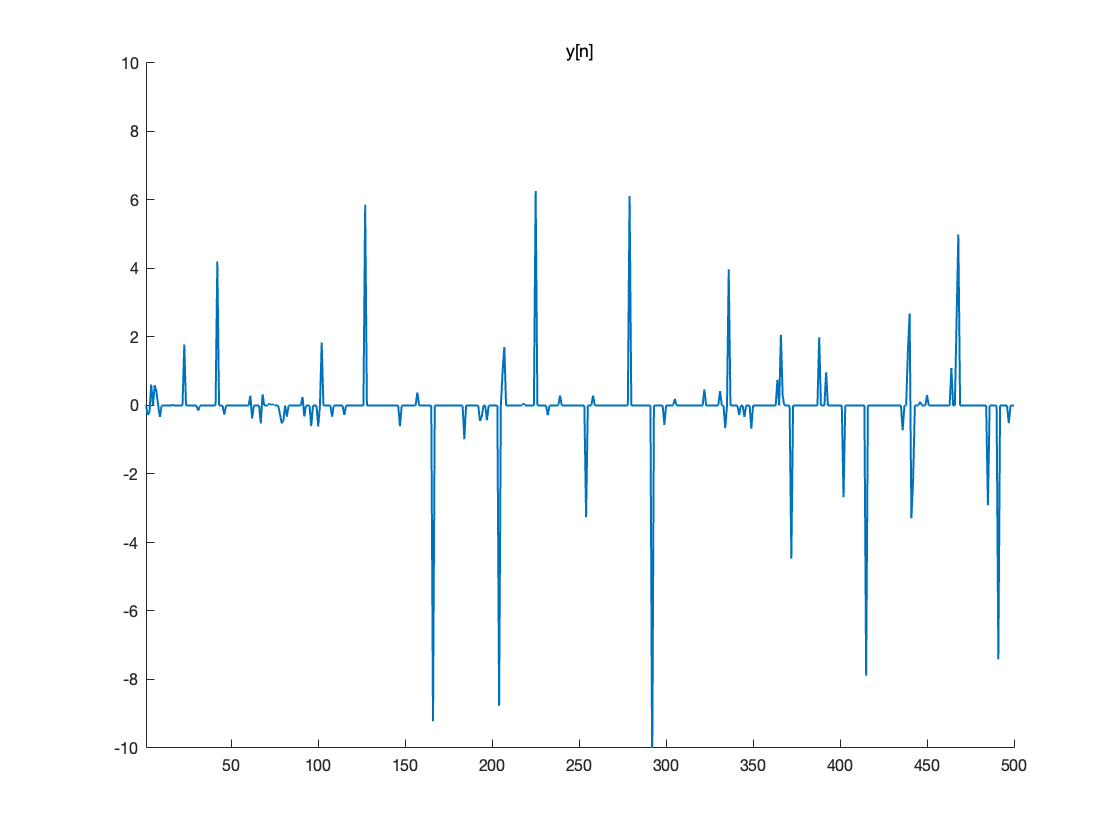


% set(gcf, 'PaperPosition', [1 1 6 6])

% print -depsc figures/output4_retrain


figure(12)
plot(1:N, output)
title('y[n]')
xlim([1,500])
ylim([-10,10])
box off


% set(gcf, 'PaperPosition', [1 1 6 6])

% print -depsc figures/output5_retrain


set_plot_defaults('off')


%% Create the convolution filter and load the proposed CNN

clc;
clear
r = 0.9;                             % Define filter
om = 0.95;
a = [1 -2*r*cos(om) r^2];
b = [1 r*cos(om)];
h = filter(b, a, [zeros(1,38) 1 zeros(1,40)]);
hh = filter(b, a, [1 zeros(1,40)]);
inverse = filter(1,hh,[zeros(1,36) 1 zeros(1,34)]);
load('sin23_2.mat');
deconvolver{1} = double(conv1);
deconvolver{2} = double(conv2);
deconvolver{3} = double(conv3);
deconvolver{4} = double(conv4);
deconvolver{5} = double(conv5);



%% Create the test signal

K = 25;
N = 500;
sigma = 0.5;
groundtruth = zeros(1, N);
index_random = randperm(N);
index = index_random(1:K);
groundtruth(index) = 10*2*(rand(1,K) - 0.5);
after_conv = conv(groundtruth,h,'same');
noise = sigma*randn(1,N);
input = after_conv + noise;


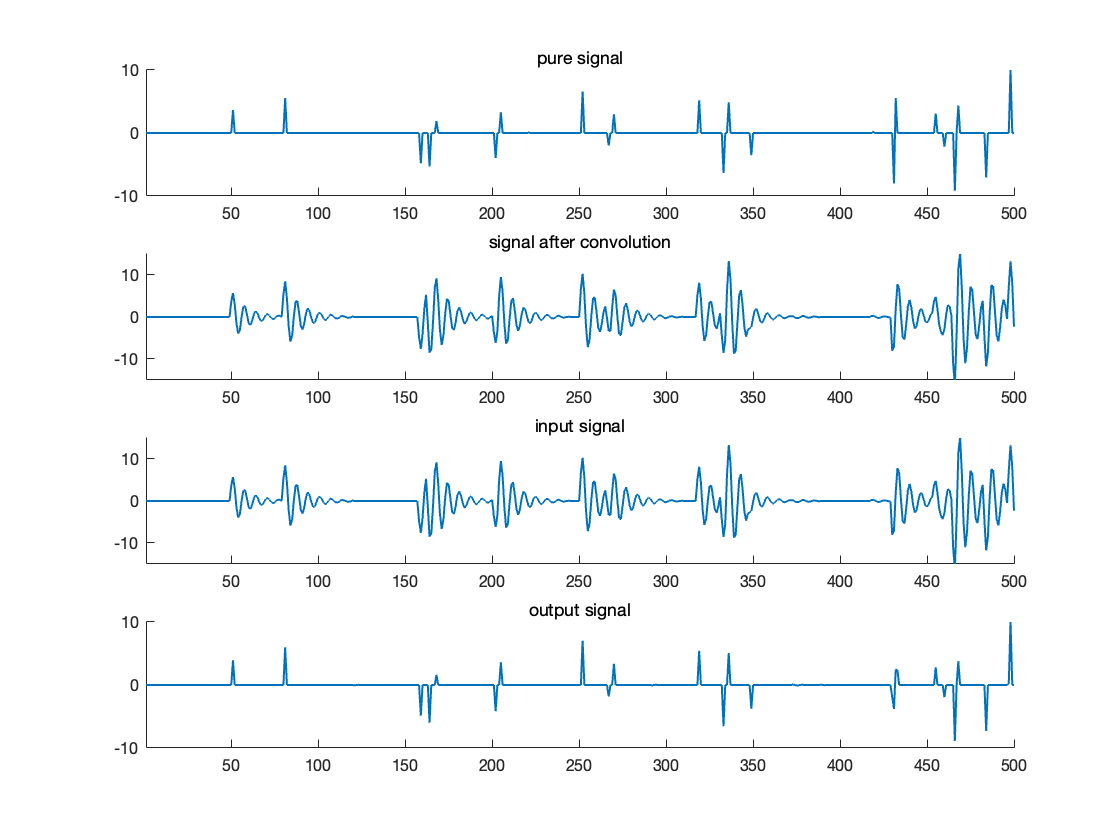

%% Plot input v.s. output in pure signal case

set_plot_defaults('on')

figure(13)
output = CNN(after_conv,deconvolver);
subplot(4,1,1)
plot(1:N, groundtruth)
xlim([1,500])
ylim([-10,10])
title('pure signal')
box off
subplot(4,1,2)
plot(1:N, after_conv)
xlim([1,500])
ylim([-15,15])
title('signal after convolution')
box off
subplot(4,1,3)
plot(1:N, after_conv)
xlim([1,500])
ylim([-15,15])
title('input signal')
box off
subplot(4,1,4)
plot(1:N, output)
xlim([1,500])
ylim([-10,10])
title('output signal')
box off


% set(gcf, 'PaperPosition', [1 1 14 12])

% print -depsc figures/pure1

MSE = mean((output-groundtruth).^2)

MSE = 0.0781

SNR = 10*log10(mean(groundtruth.^2)/MSE)

SNR = 12.2005

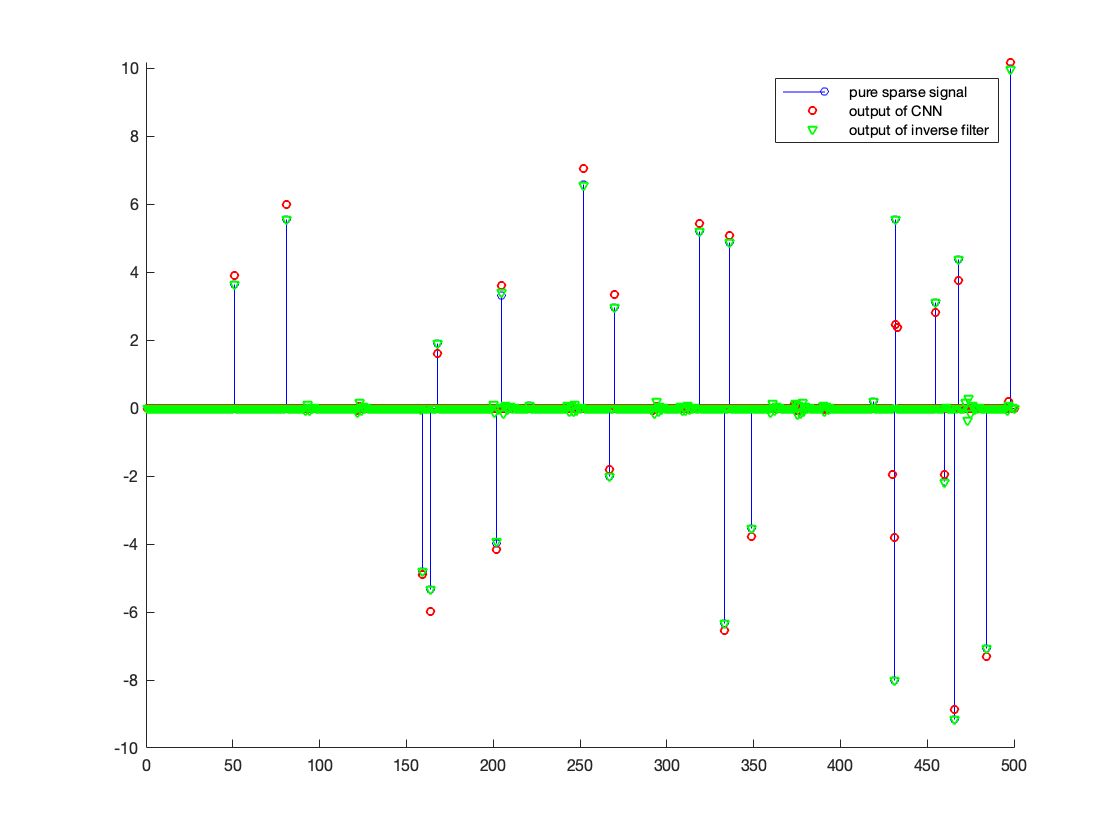


figure(14)
output1 = conv(after_conv,inverse,'same');
stem(1:N, groundtruth, 'b', 'MarkerSize', 4)
hold on
plot(1:N, output, 'ro', 'MarkerSize', 4)
hold on
plot(1:N, output1, 'gv', 'MarkerSize', 4)
hold off
legend('pure sparse signal', 'output of CNN','output of inverse filter')
box off


% set(gcf, 'PaperPosition', [1 1 14 10])

% print -depsc figures/pure2

set_plot_defaults('off')


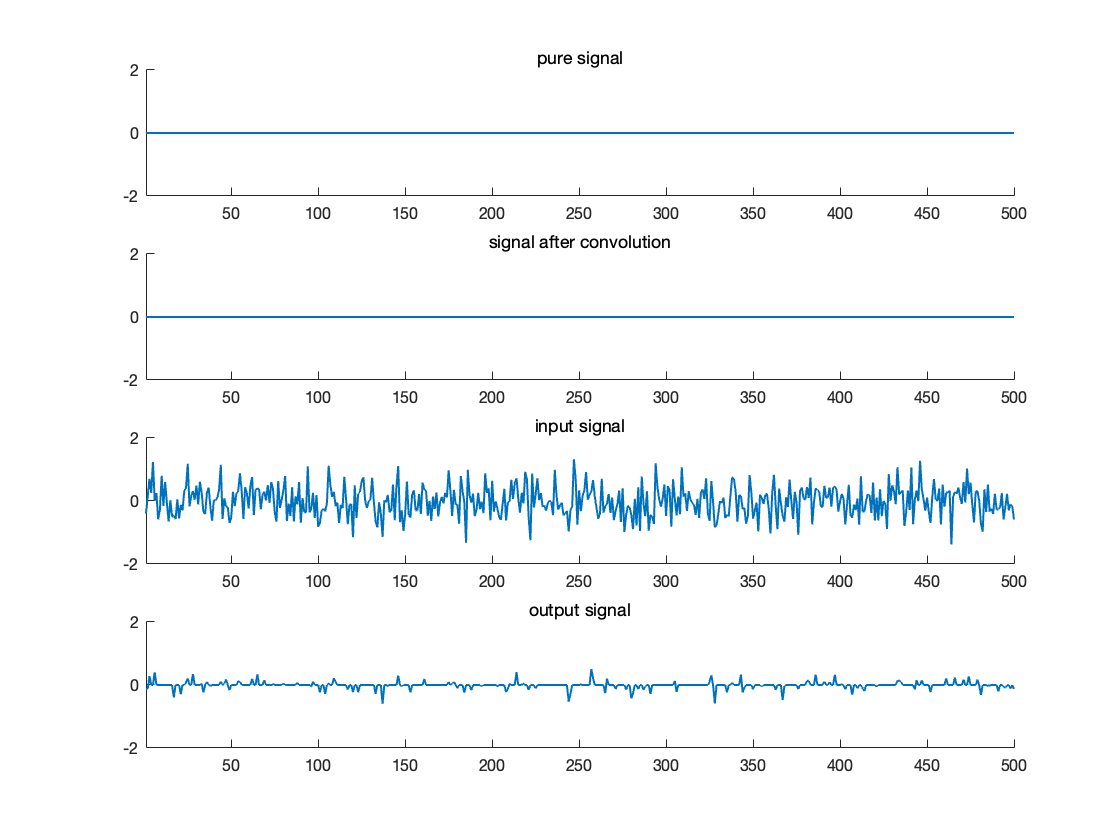

%% Plot input v.s. output in pure noise case

set_plot_defaults('on')

figure(15)
output = CNN(noise,deconvolver);
subplot(4,1,1)
plot(1:N, zeros(1,N))
xlim([1,500])
ylim([-2,2])
title('pure signal')
box off
subplot(4,1,2)
plot(1:N, zeros(1,N))
xlim([1,500])
ylim([-2,2])
title('signal after convolution')
box off
subplot(4,1,3)
plot(1:N, noise)
xlim([1,500])
ylim([-2,2])
title('input signal')
box off
subplot(4,1,4)
plot(1:N, output)
xlim([1,500])
ylim([-2,2])
title('output signal')
box off


% set(gcf, 'PaperPosition', [1 1 14 12])

% print -depsc figures/noise1

MSE = mean((output-0).^2)

MSE = 0.0115

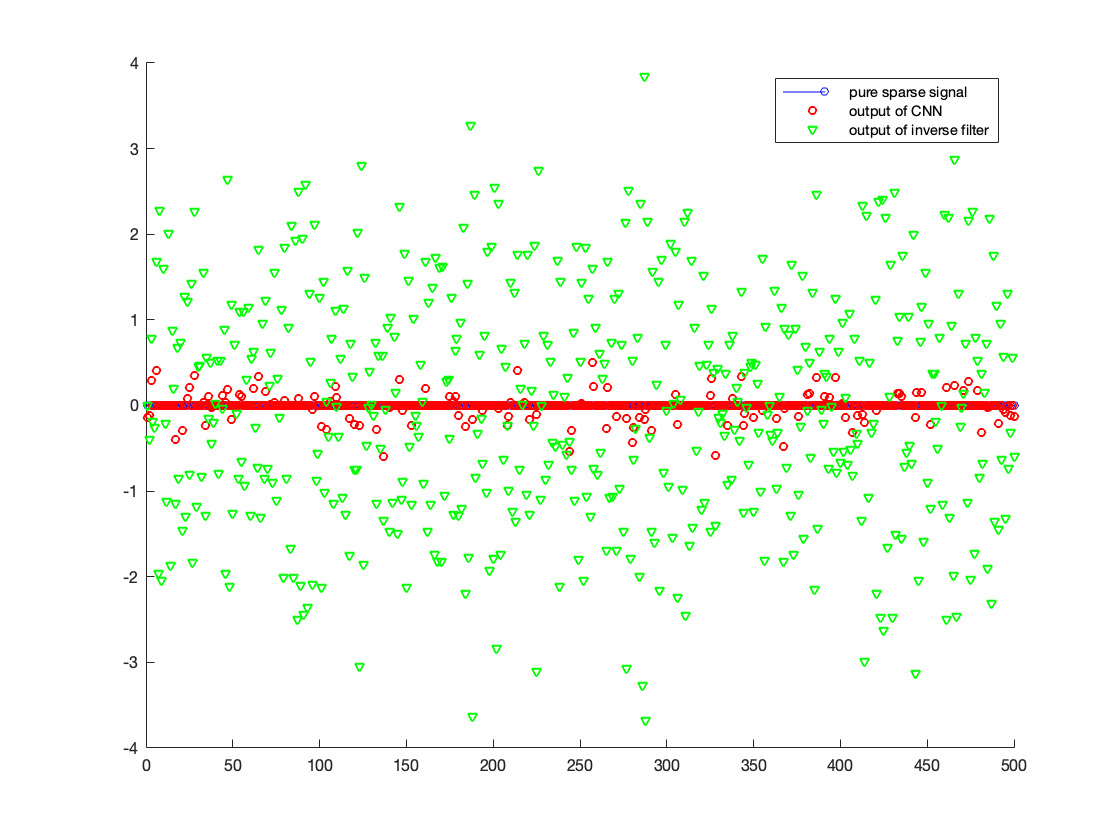

% SNR = 10*log10(mean(groundtruth.^2)/MSE)

figure(16)
output1 = conv(noise,inverse,'same');
stem(1:N, zeros(1,N), 'b', 'MarkerSize', 4)
hold on
plot(1:N, output, 'ro', 'MarkerSize', 4)
hold on
plot(1:N, output1, 'gv', 'MarkerSize', 4)
hold off
legend('pure sparse signal', 'output of CNN','output of inverse filter')
box off


% set(gcf, 'PaperPosition', [1 1 14 10])

% print -depsc figures/noise2

set_plot_defaults('off')


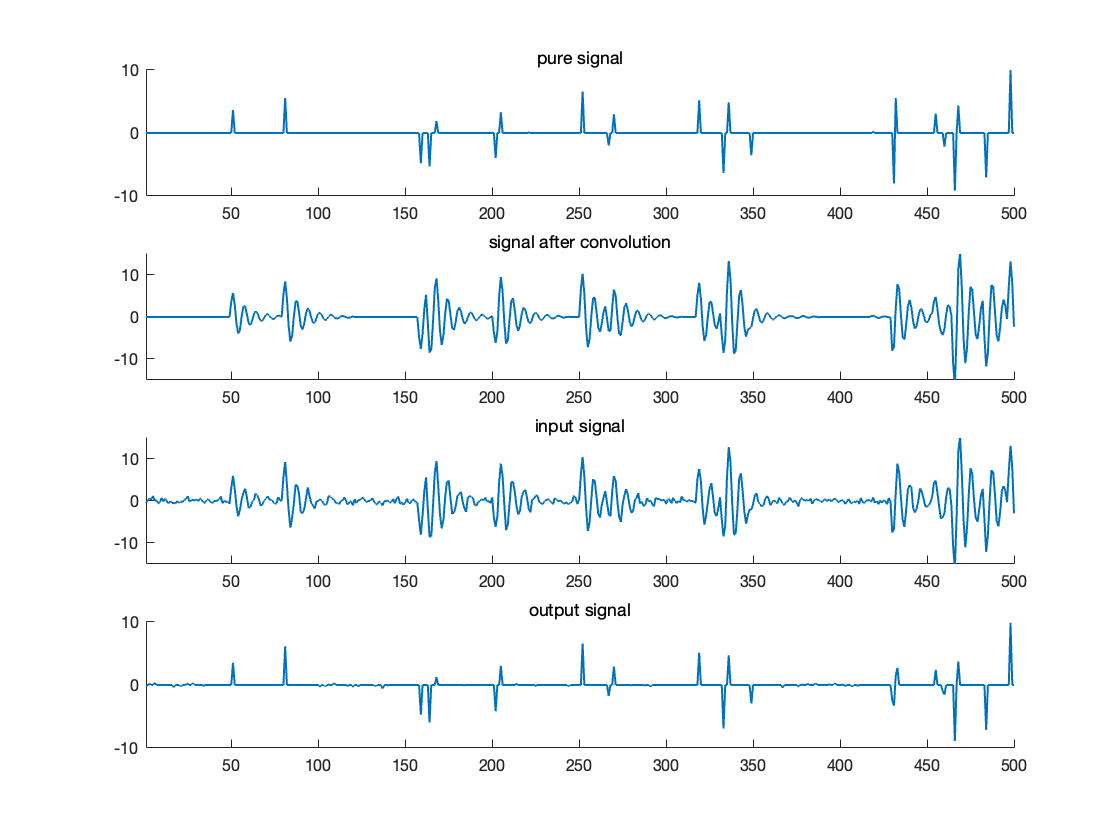

%% Plot input v.s. output in noisy signal case

set_plot_defaults('on')

figure(17)
output = CNN(input,deconvolver);
subplot(4,1,1)
plot(1:N, groundtruth)
xlim([1,500])
ylim([-10,10])
title('pure signal')
box off
subplot(4,1,2)
plot(1:N, after_conv)
xlim([1,500])
ylim([-15,15])
title('signal after convolution')
box off
subplot(4,1,3)
plot(1:N, input)
xlim([1,500])
ylim([-15,15])
title('input signal')
box off
subplot(4,1,4)
plot(1:N, output)
xlim([1,500])
ylim([-10,10])
title('output signal')
box off


% set(gcf, 'PaperPosition', [1 1 14 12])

% print -depsc figures/noisy1

MSE = mean((output-groundtruth).^2)

MSE = 0.1177

SNR = 10*log10(mean(groundtruth.^2)/MSE)

SNR = 10.4189

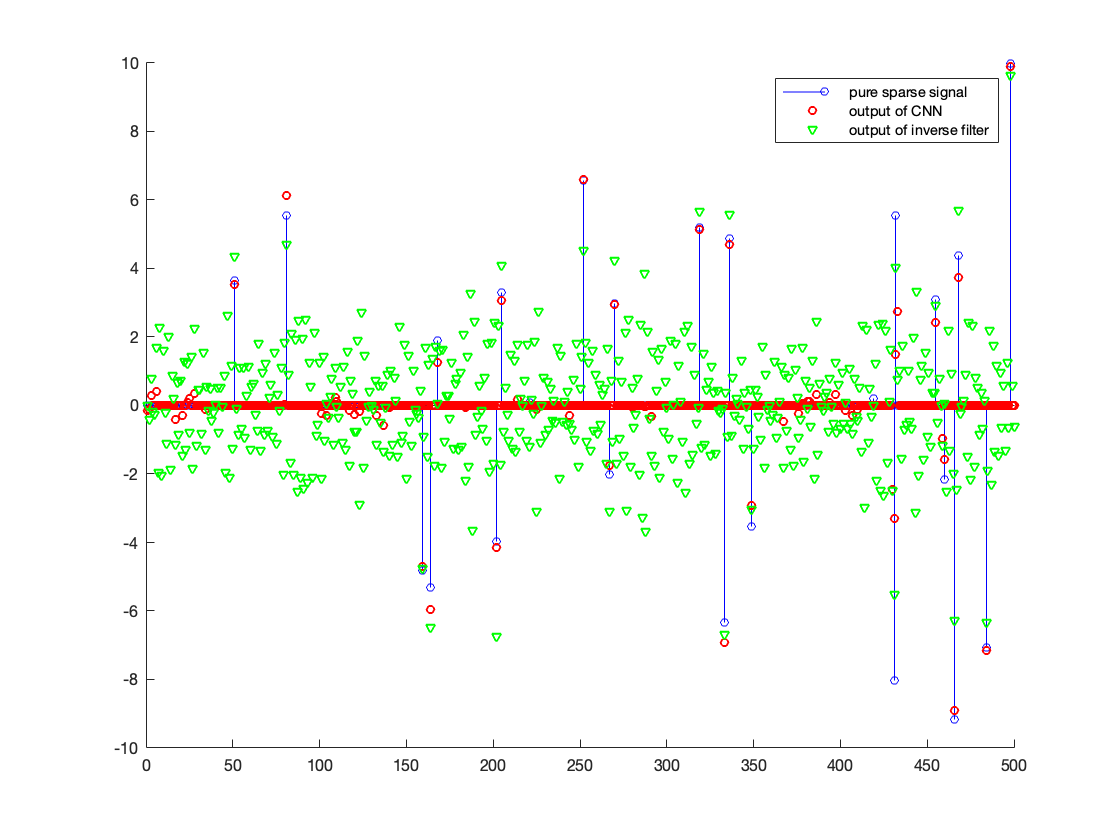


figure(18)
output1 = conv(input,inverse,'same');
stem(1:N, groundtruth, 'b', 'MarkerSize', 4)
hold on
plot(1:N, output, 'ro', 'MarkerSize', 4)
hold on
plot(1:N, output1, 'gv', 'MarkerSize', 4)
hold off
legend('pure sparse signal', 'output of CNN','output of inverse filter')
box off


% set(gcf, 'PaperPosition', [1 1 14 10])

% print -depsc figures/noisy2

set_plot_defaults('off')


%% Create input signal (noisy signal) and ground truth (pure signal) for the performance part.

% N is the total length of the pure sparse signal.
% K is the number of non-zeros in the pure sparse signal.
% As a result, 1-K/N determines the sparsity of the pure signal.

N = 500;
num = 2000;
sigma_set = logspace(log10(0.1), log10(2), 20);
% sigma_set = 0.1:0.1:2;

MSE_output_ave = zeros(3,length(sigma_set));
SNR_output_ave = zeros(3,length(sigma_set));

for m = 1:1:3
    K = 25 * m;
    for i = 1:1:length(sigma_set)

        sigma = sigma_set(i);
        SNR_output = zeros(1,num);
        SNR_input = zeros(1,num);
        MSE_output = zeros(1,num);
        for j = 1:1:num

            groundtruth = zeros(1, N);
            index_random = randperm(N);
            index = index_random(1:K);
            groundtruth(index)  = 10*2*(rand(1,K) - 0.5);
    %         groundtruth(index)  = 10*randn(1,K);
            after_conv = conv(groundtruth,h,'same');
            input_noise = sigma*randn(1,N);
            input = after_conv + input_noise;
            output = CNN(input, deconvolver);
            noise = output - groundtruth;
            MSE_output(j) = mean(noise.^2);
            SNR_output(j) = 10*log10(mean(groundtruth.^2)/MSE_output(j));

        end
        SNR_output_ave(m,i) = mean(SNR_output);
%         MSE_output_ave(m,i) = mean(MSE_output);
        MSE_output_ave(m,i) = sqrt(mean(MSE_output));

    end
end


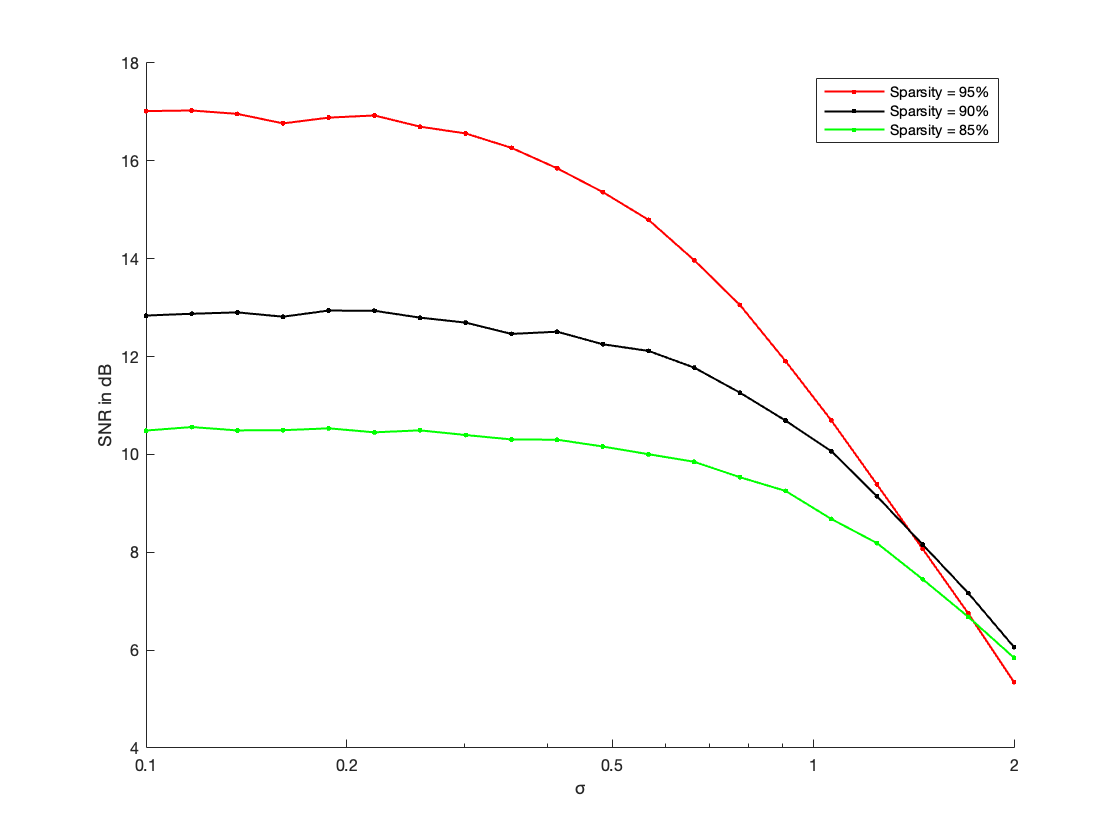

%% Plot the performance v.s. sparsity and noise level

set_plot_defaults('on')

figure(19)
semilogx(sigma_set,SNR_output_ave(1,:),'r.-',sigma_set,SNR_output_ave(2,:),'k.-',sigma_set,SNR_output_ave(3,:),'g.-')

legend('Sparsity = 95%','Sparsity = 90%','Sparsity = 85%')
xlabel('σ')
ylabel('SNR in dB')
set(gca, 'xtick', [0.1 0.2 0.5 1 2.0])
xlim([min(sigma_set) max(sigma_set)])
box off

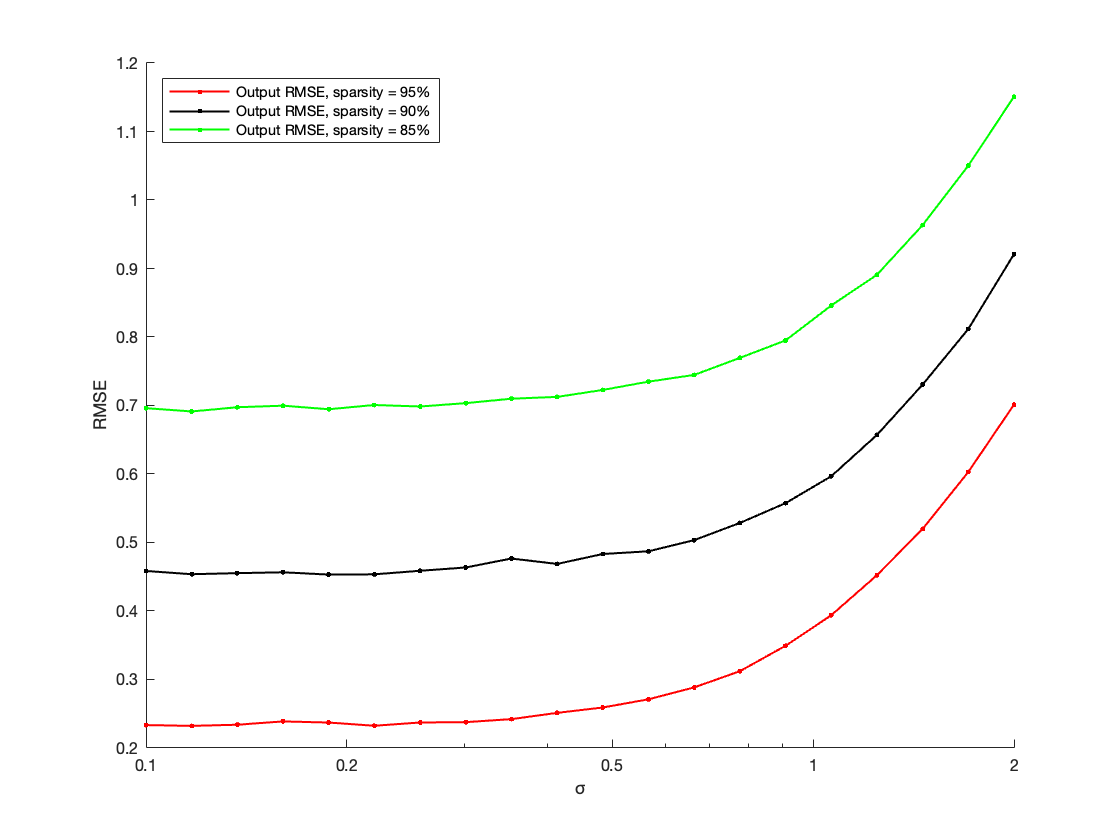


% set(gcf, 'PaperPosition', [1 1 14 10])

% print -depsc figures/SNR_sparsity

figure(20)
semilogx(sigma_set,MSE_output_ave(1,:),'r.-',sigma_set,MSE_output_ave(2,:),'k.-',sigma_set,MSE_output_ave(3,:),'g.-')

legend('Output RMSE, sparsity = 95%','Output RMSE, sparsity = 90%','Output RMSE, sparsity = 85%', 'Location','NorthWest')
xlabel('σ')
ylabel('RMSE')
set(gca, 'xtick', [0.1 0.2 0.5 1 2.0])
xlim([min(sigma_set) max(sigma_set)])
box off


% set(gcf, 'PaperPosition', [1 1 14 10])

% print -depsc figures/MSE_sparsity

set_plot_defaults('off')


%% Create the performance form for multiple sparsities.


SNR_output_ave = zeros(1,5);
MSE_output_ave = zeros(1,5);

N = 500;
num = 10000;

for i = 1:1:5
    
    sparsity = 2.5 * (i + 1);
    K = round(500 * sparsity/100);
    SNR_output = zeros(1,num);
    MSE_output = zeros(1,num);
    for j = 1:1:num
        
        groundtruth = zeros(1, N);
        index_random = randperm(N);
        index = index_random(1:K);
        groundtruth(index)  = 10*2*(rand(1,K) - 0.5);
%         groundtruth(index)  = 10*randn(1,K);
        sigma = 2 * rand();
        input_noise = sigma*randn(1,N);
        after_conv = conv(groundtruth,h,'same');
        input = after_conv + input_noise;
        output = CNN(input, deconvolver);
        noise = output - groundtruth;
        MSE_output(j) = mean(noise.^2);
        SNR_output(j) = 10*log10(mean(groundtruth.^2)/MSE_output(j));
        
    end
    SNR_output_ave(i) = mean(SNR_output);
    MSE_output_ave(i) = mean(MSE_output);
    
end

SNR_output_ave

SNR_output_ave =    11.4410   10.7692   10.0935    9.2702    8.6978


MSE_output_ave

MSE_output_ave =     0.1860    0.2853    0.4011    0.5750    0.7527


%% Create the performance form for multiple noise levels

SNR_output_ave = zeros(1,8);
MSE_output_ave = zeros(1,8);

for i = 1:1:8
    
    sigma = 0.25 * i;
    SNR_output = zeros(1,num);
    MSE_output = zeros(1,num);
    for j = 1:1:num
        
        K = ceil(50*rand()+25);
        groundtruth = zeros(1, N);
        index_random = randperm(N);
        index = index_random(1:K);
        groundtruth(index)  = 10*2*(rand(1,K) - 0.5);
%         groundtruth(index)  = 10*randn(1,K);
        input_noise = sigma*randn(1,N);
        after_conv = conv(groundtruth,h,'same');
        input = after_conv + input_noise;
        output = CNN(input, deconvolver);
        noise = output - groundtruth;
        MSE_output(j) = mean(noise.^2);
        SNR_output(j) = 10*log10(mean(groundtruth.^2)/MSE_output(j));
        
    end
    SNR_output_ave(i) = mean(SNR_output);
    MSE_output_ave(i) = mean(MSE_output);
    
end

SNR_output_ave

SNR_output_ave =    12.9217   12.3641   11.4108   10.2006    9.0257    7.8732    6.8385    5.9092


MSE_output_ave

MSE_output_ave =     0.2382    0.2583    0.2982    0.3655    0.4609    0.5801    0.7236    0.8867


%% Compare the proposed CNN with other methods. Create all the methods.

r = 0.9;                             % Define filter
om = 0.95;
a = [1 -2*r*cos(om) r^2];
b = [1 r*cos(om)];
h = filter(b, a, [zeros(1,38) 1 zeros(1,40)]);
hh = filter(b, a, [1 zeros(1,40)]);
inverse = filter(1,hh,[zeros(1,36) 1 zeros(1,34)]);
load('sin23_2.mat');
deconvolver1{1} = double(conv1);
deconvolver1{2} = double(conv2);
deconvolver1{3} = double(conv3);
deconvolver1{4} = double(conv4);
deconvolver1{5} = double(conv5);
load('5layer_compare.mat');
deconvolver2{1} = conv1;
deconvolver2{2} = conv2;
deconvolver2{3} = conv3;
deconvolver2{4} = conv4;
deconvolver2{5} = conv5;
load('7layer_compare.mat');
deconvolver3{1} = conv1;
deconvolver3{2} = conv2;
deconvolver3{3} = conv3;
deconvolver3{4} = conv4;
deconvolver3{5} = conv5;
deconvolver3{6} = conv6;
deconvolver3{7} = conv7;


%% Create input signal (noisy signal) and ground truth (pure signal).

% N is the total length of the pure sparse signal.
% K is the number of non-zeros in the pure sparse signal.
% As a result, 1-K/N determines the sparsity of the pure signal.

N = 500;
num = 1000;
sigma_set = 0.1:0.1:2;
SNR_1 = zeros(1,length(sigma_set));
MSE_1 = zeros(1,length(sigma_set));
SNR_2 = zeros(1,length(sigma_set));
MSE_2 = zeros(1,length(sigma_set));
SNR_3 = zeros(1,length(sigma_set));
MSE_3 = zeros(1,length(sigma_set));
SNR_4 = zeros(1,length(sigma_set));
MSE_4 = zeros(1,length(sigma_set));

for i = 1:1:length(sigma_set)
    
    sigma = sigma_set(i);
    SNR_num1 = zeros(1,num);
    MSE_num1 = zeros(1,num);
    SNR_num2 = zeros(1,num);
    MSE_num2 = zeros(1,num);
    SNR_num3 = zeros(1,num);
    MSE_num3 = zeros(1,num);
    SNR_num4 = zeros(1,num);
    MSE_num4 = zeros(1,num);
    
    for j = 1:1:num
        
        K = ceil(50*rand()+25);
        groundtruth = zeros(1, N);
        index_random = randperm(N);
        index = index_random(1:K);
        groundtruth(index)  = 10*2*(rand(1,K) - 0.5);
        after_conv = conv(groundtruth,h,'same');
%         groundtruth(index)  = 10*randn(1,K);
        input = after_conv + sigma*randn(1,N);
        
        output = CNN(input, deconvolver1);
        noise = output - groundtruth;
        MSE_num1(j) = mean(noise.^2);
        SNR_num1(j) = 10*log10(mean(groundtruth.^2)/MSE_num1(j));       
        
        output = CNN(input, deconvolver2);
        noise = output - groundtruth;
        MSE_num2(j) = mean(noise.^2);
        SNR_num2(j) = 10*log10(mean(groundtruth.^2)/MSE_num2(j));       
        
        output = CNN(input, deconvolver3);
        noise = output - groundtruth;
        MSE_num3(j) = mean(noise.^2);
        SNR_num3(j) = 10*log10(mean(groundtruth.^2)/MSE_num3(j));
        
        output = conv(input,inverse,'same');
        noise = output - groundtruth;
        MSE_num4(j) = mean(noise.^2);
        SNR_num4(j) = 10*log10(mean(groundtruth.^2)/MSE_num4(j));
          
    end
    SNR_1(i) = mean(SNR_num1);
%     MSE_1(i) = mean(MSE_num1);
    MSE_1(i) = sqrt(mean(MSE_num1));
    SNR_2(i) = mean(SNR_num2);
%     MSE_2(i) = mean(MSE_num2);
    MSE_2(i) = sqrt(mean(MSE_num2));
    SNR_3(i) = mean(SNR_num3);
%     MSE_3(i) = mean(MSE_num3);
    MSE_3(i) = sqrt(mean(MSE_num3));
    SNR_4(i) = mean(SNR_num4);
%     MSE_4(i) = mean(MSE_num4);
    MSE_4(i) = sqrt(mean(MSE_num4));
    
end


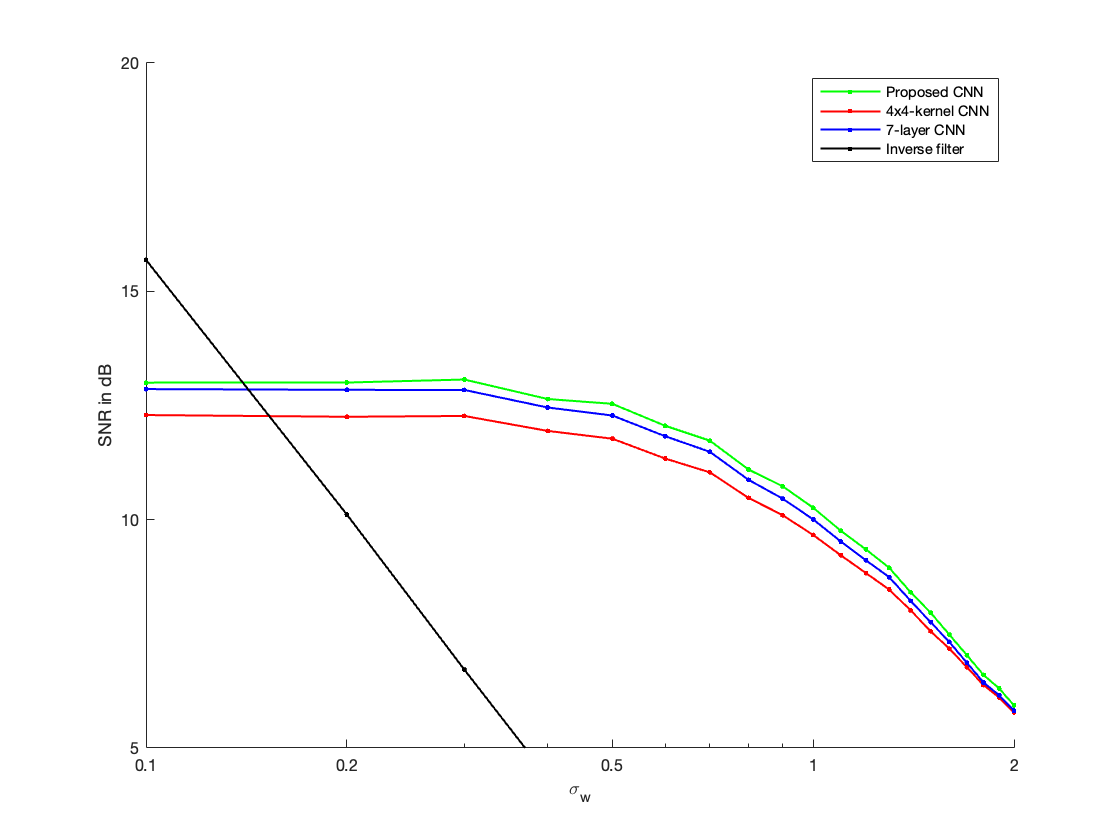

%% Plot the performance figures of different methods.

set_plot_defaults('on')

figure(21)
clf
semilogx(sigma_set, SNR_1,'g.-', sigma_set, SNR_2,'r.-', sigma_set, SNR_3,'b.-', sigma_set, SNR_4, 'k.-');
legend('Proposed CNN', '4x4-kernel CNN', '7-layer CNN', 'Inverse filter');
xlabel('\sigma_w')
ylabel('SNR in dB')
set(gca, 'xtick', [0.1 0.2 0.5 1 2.0])
xlim([min(sigma_set) max(sigma_set)])
ylim([5,20])
box off

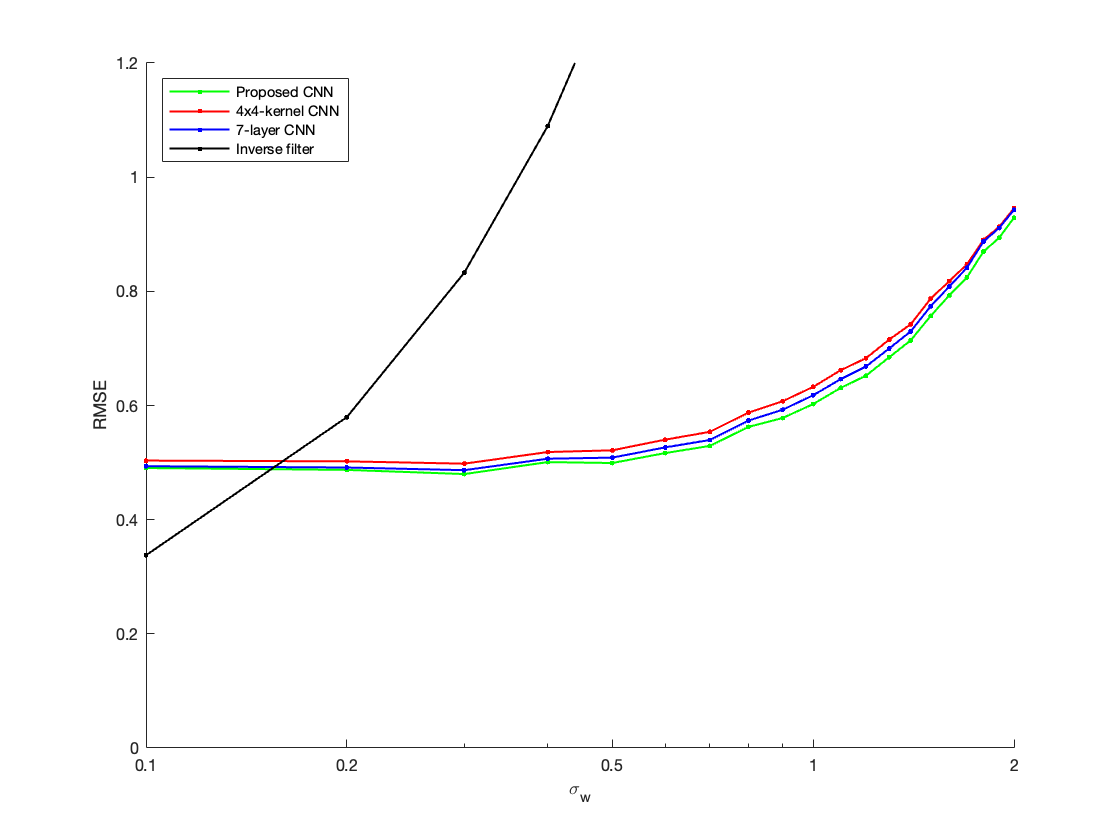


% set(gcf, 'PaperPosition', [1 1 14 10])

% print -depsc figures/SNR_average

figure(22)
clf
semilogx(sigma_set, MSE_1,'g.-', sigma_set, MSE_2,'r.-', sigma_set, MSE_3,'b.-', sigma_set, MSE_4,'k.-');
legend('Proposed CNN', '4x4-kernel CNN', '7-layer CNN', 'Inverse filter', 'Location','NorthWest');
xlabel('\sigma_w')
ylabel('RMSE')
set(gca, 'xtick', [0.1 0.2 0.5 1 2.0])
xlim([min(sigma_set) max(sigma_set)])
ylim([0,1.2])
box off


% set(gcf, 'PaperPosition', [1 1 14 10])

% print -depsc figures/MSE_average

set_plot_defaults('off')


%% Create the comparison form for different methods.

num = 1000;
SNR_num1 = zeros(1,num);
MSE_num1 = zeros(1,num);
SNR_num2 = zeros(1,num);
MSE_num2 = zeros(1,num);
SNR_num3 = zeros(1,num);
MSE_num3 = zeros(1,num);
SNR_num4 = zeros(1,num);
MSE_num4 = zeros(1,num);



for j = 1:1:num
        
    sigma = 2;                              % change from 0 to 2 with an interval of 0.5.
    K = ceil(50*rand()+25);
    groundtruth = zeros(1, N);
    index_random = randperm(N);
    index = index_random(1:K);
    groundtruth(index)  = 10*2*(rand(1,K) - 0.5);
    after_conv = conv(groundtruth,h,'same');
%         groundtruth(index)  = 10*randn(1,K);
    ini_noise = sigma*randn(1,N);
    input = after_conv + ini_noise;
    
    output = CNN(input, deconvolver1);
    noise = output - groundtruth;
    MSE_num1(j) = mean(noise.^2);
    SNR_num1(j) = 10*log10(mean(groundtruth.^2)/MSE_num1(j));

    output = CNN(input, deconvolver2);
    noise = output - groundtruth;
    MSE_num2(j) = mean(noise.^2);
    SNR_num2(j) = 10*log10(mean(groundtruth.^2)/MSE_num2(j));

    output = CNN(input, deconvolver3);
    noise = output - groundtruth;
    MSE_num3(j) = mean(noise.^2);
    SNR_num3(j) = 10*log10(mean(groundtruth.^2)/MSE_num3(j));

    output = conv(input,inverse,'same');
    noise = output - groundtruth;
    MSE_num4(j) = mean(noise.^2);
    SNR_num4(j) = 10*log10(mean(groundtruth.^2)/MSE_num4(j));
    
end

SNR_1 = mean(SNR_num1)

SNR_1 = 5.8902

MSE_1 = mean(MSE_num1)

MSE_1 = 0.8636

SNR_2 = mean(SNR_num2)

SNR_2 = 5.7362

MSE_2 = mean(MSE_num2)

MSE_2 = 0.8920

SNR_3 = mean(SNR_num3)

SNR_3 = 5.7450

MSE_3 = mean(MSE_num3)

MSE_3 = 0.8961

SNR_4 = mean(SNR_num4)

SNR_4 = -9.5516

MSE_4 = mean(MSE_num4)

MSE_4 = 28.3626